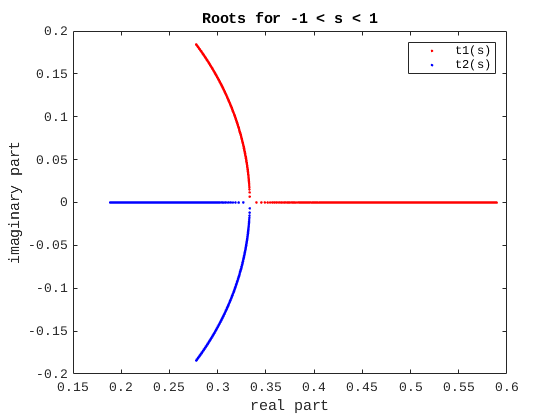

% a.
format long

close all
t1 = @(s) (6+s+sqrt((6+s).^2-36))/18; % short hand for defining functions in MATLAB
t2 = @(s) (6+s-sqrt((6+s).^2-36))/18;
s = linspace(-1,1,800);
plot(t1(s),'r.')
hold on
plot(t2(s),'b.')
xlabel('real part'), ylabel('imaginary part')
xlim([0.15 0.6])
ylim([-0.2 0.2])
title('Roots for -1 < s < 1')
legend('t1(s)','t2(s)')
hold off

% b. Error Calculation at s = -0.1
s = -0.1;
r = roots([9, -(6+s), 1]);
err = min(abs(r(1)-t1(s)), abs(r(1)-t2(s)))

err =      5.928593550334434e-17


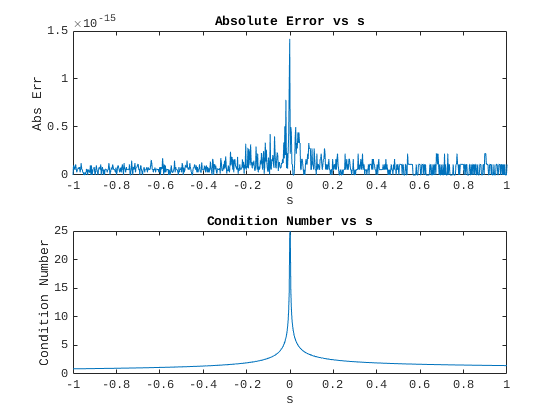


% c. Condition Numbers and Errors linspace
s = linspace(-1,1,800);
r = zeros(800,1);
for i = 1:800
    rtmp = roots([9, -(6 + s(i)), 1]);
    r(i) = rtmp(1);
end
errs = min([abs(r-t1(s)) abs(r-t2(s))], [], 2);
conds = abs(t1(s) ./ (t1(s)-t2(s)));

subplot(2,1,1)
plot(s, errs)
title('Absolute Error vs s')
xlabel('s')
ylabel('Abs Err')
subplot(2,1,2)
plot(s, conds)
title('Condition Number vs s')
xlabel('s')
ylabel('Condition Number')

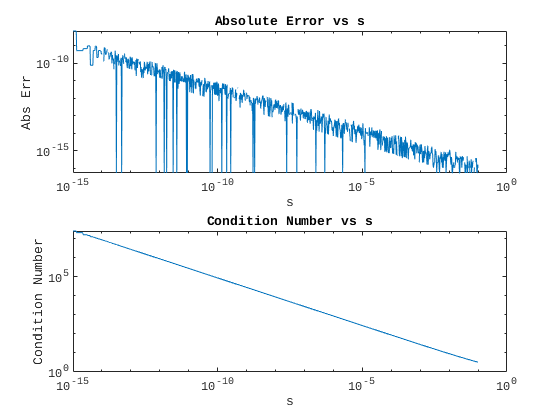

% d. Condition numbers and errors for logspace
s = logspace(-15,-1,1000);
r = zeros(1,1000);
for i = 1:1000
    rtmp = roots([9, -(6 + s(i)), 1]);
    r(i) = rtmp(1);
end
errs = min([abs(r-t1(s)); abs(r-t2(s))], [], 1);
conds = abs(t1(s) ./ (t1(s)-t2(s)));

figure()
subplot(2,1,1)
loglog(s, errs)
title('Absolute Error vs s')
xlabel('s')
ylabel('Abs Err')
subplot(2,1,2)
loglog(s, conds)
title('Condition Number vs s')
xlabel('s')
ylabel('Condition Number')

% Problem 2 a.
condf = @(x) abs((x .* exp(x)) ./ (exp(x) - 1) - 1);

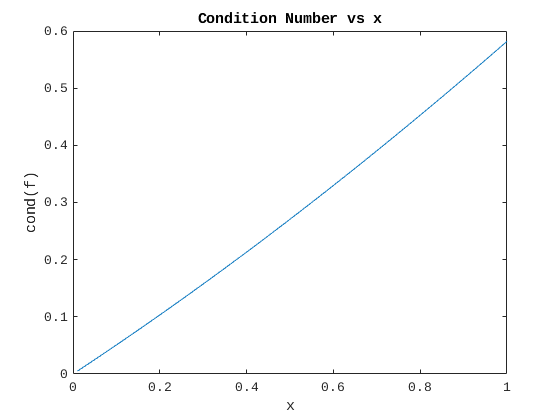

% b.
x = linspace(0,1,100);
conds = condf(x);

figure()
plot(x,conds)
title("Condition Number vs x")
xlabel('x')
ylabel('cond(f)')

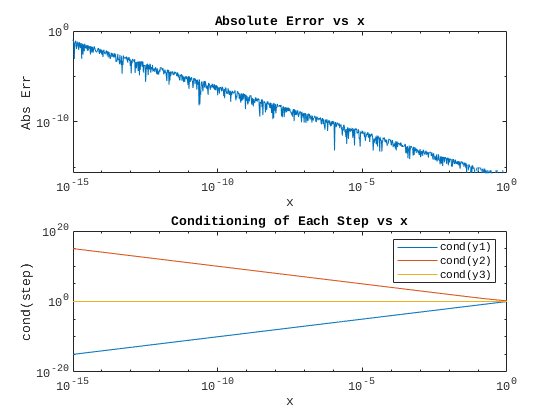

% d.
x = logspace(-15, 0, 1000);
y1 = exp(x);
y2 = y1 - 1;
y3 = y2 ./ x;

condy1 = @(x) abs(x);
condy2 = @(x) abs(exp(x) ./ (exp(x) - 1));
condy3 = ones(1,1000);

errs = abs(y3 - expm1(x) ./ x);

figure()
subplot(2,1,2)
loglog(x,condy1(x))
hold on
loglog(x, condy2(x))
loglog(x, condy3)
hold off
title('Conditioning of Each Step vs x')
xlabel('x')
ylabel('cond(step)')
legend('cond(y1)','cond(y2)','cond(y3)')
subplot(2,1,1)
loglog(x, errs)
title('Absolute Error vs x')
xlabel('x')
ylabel('Abs Err')

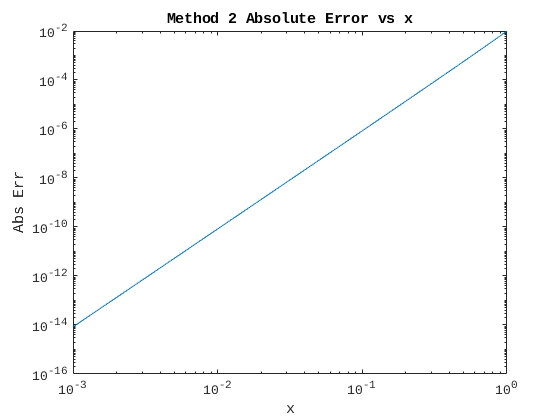

% e.
x = linspace(0,1,1000);

f2 = @(x) 1 + x ./ (factorial(2)) + x.^2./ factorial(3) + x.^3./ factorial(4);

errs = abs(f2(x) - expm1(x) ./ x);

figure()
loglog(x,errs)
title('Method 2 Absolute Error vs x')
xlabel('x')
ylabel('Abs Err')